defaultDir = 'M:\Bergles Lab Data\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 5 - In vivo drug infusion');

%%load image and normalize
list = loadFileList('.\Data\MRS2500 IP\*_SC.tif');
img = loadTif(list{1},16);

[dFoF] = normalizeImg(img,5,1);

Bleach correction finished. Subtracting baseline...


[m,n,t] = size(dFoF);
subtMean = mean(reshape(dFoF,m*n,t),1);
signalCorrected = reshape(reshape(dFoF,m*n,t)-subtMean,m,n,t);

figure;
[m,n,t] = size(signalCorrected);
res = smooth(reshape(signalCorrected,m*n,t));
res = reshape(res,m*n,t)

res = 11664×6000 single matrix
    0.0330   -0.0002   -0.0274   -0.0051   -0.0169   -0.0279   -0.0431   -0.0348   -0.0095   -0.0401   -0.0222   -0.0400   -0.0346   -0.0341   -0.0513   -0.0498   -0.0291   -0.0341   -0.0253   -0.0378   -0.0548   -0.0641   -0.0602   -0.0611   -0.0576   -0.0302   -0.0421   -0.0493   -0.0312   -0.0341   -0.0183   -0.0388   -0.0300   -0.0215   -0.0435   -0.0372   -0.0484   -0.0224   -0.0395   -0.0312   -0.0169   -0.0211   -0.0139   -0.0147   -0.0009   -0.0514   -0.0148   -0.0412   -0.0018   -0.0071
    0.0047   -0.0115   -0.0327   -0.0274   -0.0432   -0.0360   -0.0664   -0.0479   -0.0153   -0.0503   -0.0518   -0.0588   -0.0528   -0.0670   -0.0809   -0.0916   -0.0523   -0.0435   -0.0570   -0.0639   -0.0742   -0.0700   -0.0687   -0.0814   -0.0685   -0.0594   -0.0487   -0.0631   -0.0544   -0.0479   -0.0419   -0.0410   -0.0364   -0.0298   -0.0618   -0.0598   -0.0486   -0.0304   -0.0400   -0.0362   -0.0435   -0.0322   -0.0311   -0.0387   -0.0285   -0.0606   -0.03

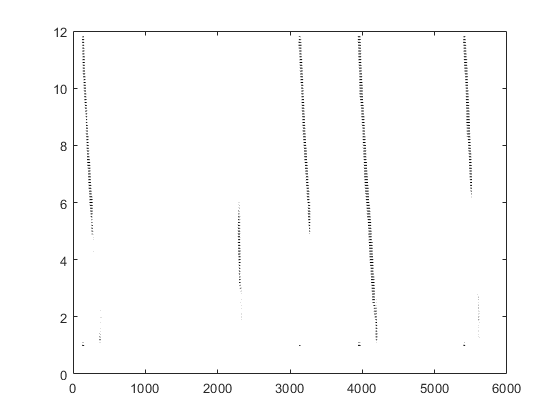


resThr = mean(res,2)+3*std(res,[],2);
bin = [];
for i = 1:size(resThr,1)
    bin(:,i) = res(i,:) > resThr(i);
end
bin(bin == 0) = NaN;

figure;
count = 0;
for i=108*50:1:108*50+108
    plot(bin(:,i)+count*.1,'Color','k'); hold on;
    count = count + 1;
end

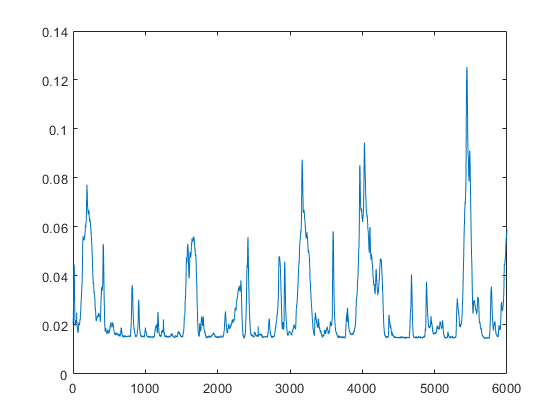


figure;
plot(std(res,[],1));

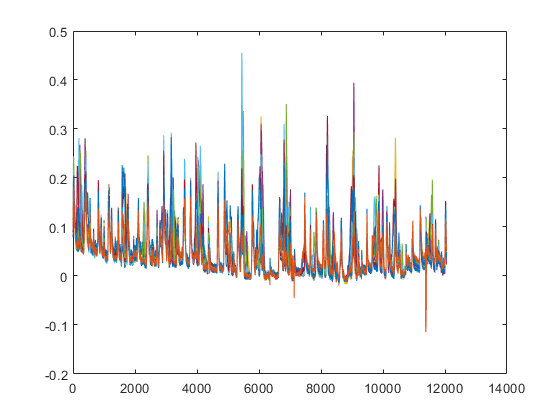


%%testing 

SCsignal = SC_activity;
%normalize
Fo = prctile(SCsignal,5,1);
dFoF = (single(SCsignal) - single(Fo)) ./ single(Fo);

figure;
plot(dFoF);

subtMean = mean(dFoF,2);
figure; plot(dFoF); hold on; plot(subtMean,'LineWidth',4);

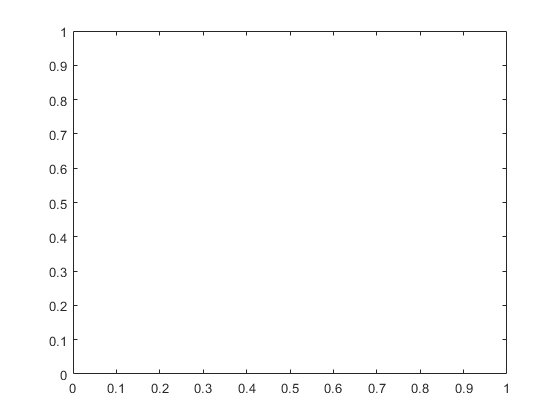

dFoF_subt = dFoF - subtMean;
dFoF_subt(dFoF_subt < 0) = 0;
figure; 
for i = 1:size(dFoF_subt,2)
    plot(dFoF_subt(:,i) + ((i-1)*.1)); hold on;
end


re = reshape(dFoF_subt,4,4,12048);

Error using reshape
To RESHAPE the number of elements must not change.

implay(re);

    [r,c] = find(LSCmask); %%assume rectangle ROI
    width = max(c) - min(c) + 1;
    height = max(r) - min(r) + 1;
    [idx] = find(LSCmask);
    
    SCimage = zeros(height,width, size(dFoF,3));
    
    parfor i = 1:size(dFoF,3)
        temp = dFoF(:,:,i);
        temp = temp(idx);
        SCimage(:,:,i) = reshape(temp,height, width);
    end
    
    [m,n,t] = size(SCimage);
    subtMean = mean(reshape(SCimage,m*n,t),1);
    signalCorrected = reshape(smooth(reshape(SCimage,m*n,t)-subtMean),m,n,t);

Error using reshape
To RESHAPE the number of elements must not change.

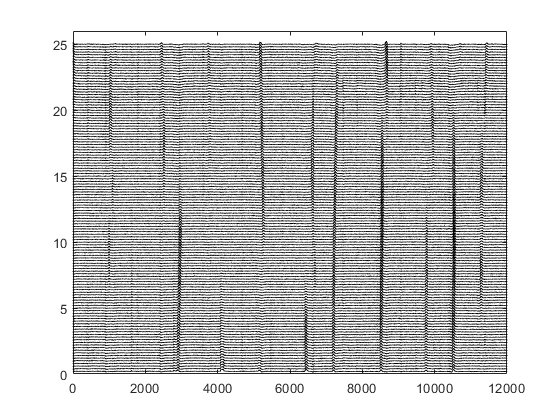

figure;
for i = 1:1:size(signalCorrected,2)
    plot(squeeze(signalCorrected(50,i,:))+.2*i,'Color','k'); hold on;
end
xlim([0 12000]);
ylim([0 26])

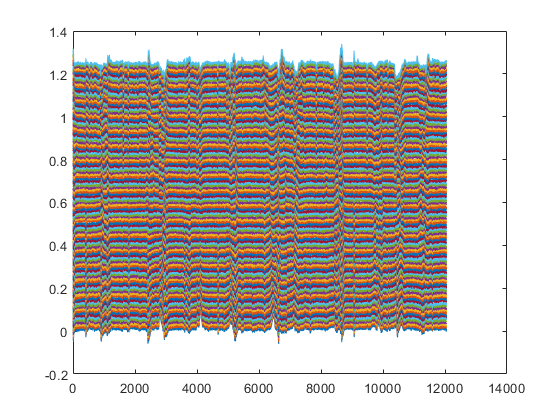

figure;
mSC = squeeze(mean(signalCorrected,1));
for i = 1:1:size(mSC,1)
    plot(mSC(i,:)+.01*i); hold on;
end


resThr = mean(mSC,2)+3*std(mSC,[],2);
bin = [];
for i = 1:size(resThr,1)
    bin(:,i) = mSC(i,:) > resThr(i);
end
%bin(bin == 0) = NaN;
bin = imgaussfilt(bin,5)

bin =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

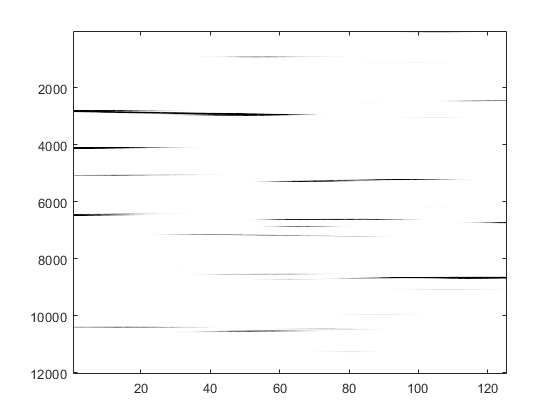

figure;
imagesc(bin.*mSC');
colormap(flipud(gray));
caxis([0 .05])